# Eigenvalues and Eigenvectors

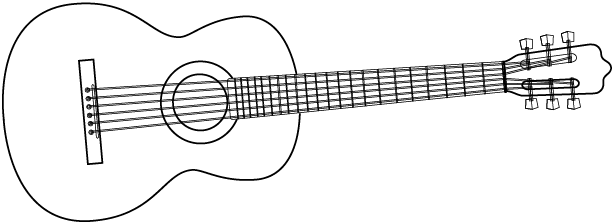

Each string of a guitar vibrates at a fundamental frequency. Additional vibrational modes, known as harmonics, are also present. Together, they produce rich, complementary tones. Natural vibrations like these can be identified by performing an eigenanalysis of a computational model of the system.

In this script, you'll learn the fundamentals of eigenvectors and eigenvalues. 

 This live script is intended to be used with the code shown. Select the `VIEW` tab and switch to `Output Inline`.

 If you find the MATLAB coding in this script to be challenging, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

## Definition

**Definition**. Consider a square $n \times n$ matrix $\mathbf{A}$. A vector $\mathbf{v}$ is said to be an *eigenvector* of $\mathbf{A}$ with a corresponding *eigenvalue* $\lambda$ if

    $\mathbf{A v} = \lambda \mathbf{v}$.

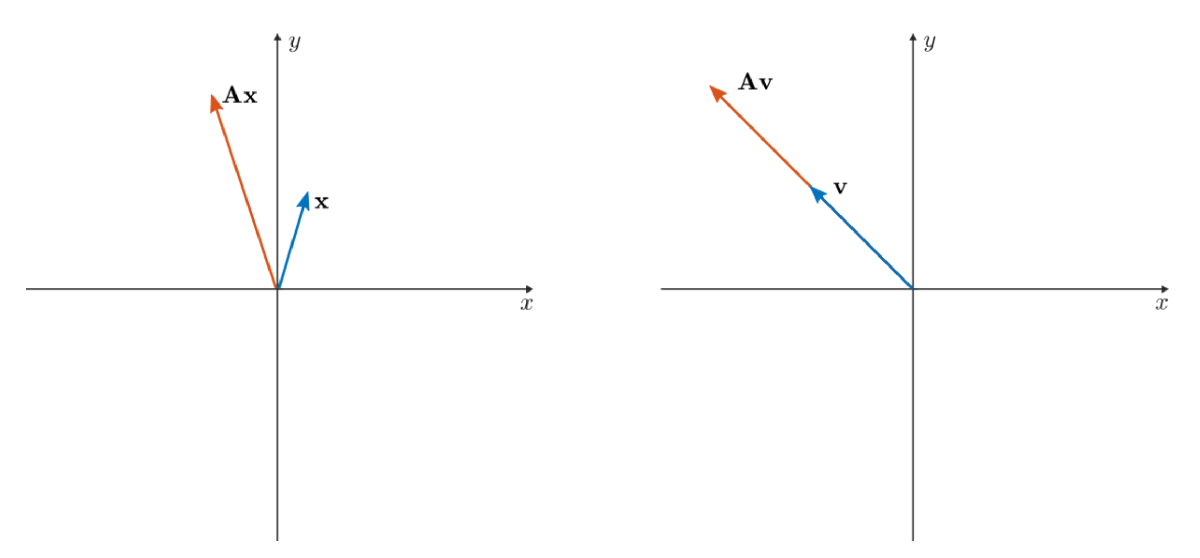

*Most vectors *$\mathbf{x}$* will point in a different direction when multiplied by *$\mathbf{A}$* (left panel). Eigenvectors are the exception. An eigenvector is any vector that points in the same direction after being multiplied by *$\mathbf{A}$* (right panel).*

  **Try**

Consider the 2x2 matrix $\mathbf A$:

A = sym([2 -1; -1 2])

- A vector $\mathbf{x}$ is defined through its angle with the $x$-axis below. Adjust the angle $\theta$ using the slider so that $\mathbf{x}$ is an eigenvector of $\mathbf{A}$.

- Is there more than one eigenvector of $\mathbf{A}$?

- Based on the values of $\mathbf{A}$ and $\mathbf{Ax}$, what are eigenvalues that correspond to the eigenvectors that you found?

thetad =sym(135);  % In degrees
x = sym([cosd(thetad); sind(thetad)]);
Ax = sym(A)*x;
% Plot the vectors
figure
hold on
setup2DVectorPlot([-2.5 2.5 -2.5 2.5])
plotVector2D([0 0],double(x),"\mathbf{x}",-0.5)
plotVector2D([0 0],double(Ax),"\mathbf{Ax}",0.5)
hold off
x
Ax

 **Reflect**

- Suppose that there is an eigenvector $\mathbf{v}$ that satisfies the definition. Will $-\mathbf{v}$ also satisfy the definition?

## Solving for eigenvalues and eigenvectors

You can solve for the eigenvalues and eigenvectors of a matrix analytically using two steps:

- Find the eigenvalues of $\mathbf{A}$ by solving $\det(\mathbf{A}-\lambda \mathbf{I}
) = 0$ for $\lambda$.

- Solve for the eigenvectors of $\mathbf{A}$ by solving the linear system $(\mathbf{A} -  \lambda \mathbf{I} )\mathbf{v} = \mathbf{0}}$ for each $\lambda$.

### Eigenvalues 

To understand the first step (solving for the eigenvalues), consider the definition:

    
$$\mathbf{A v} = \lambda \mathbf{v}$$


You can rewrite the definition as:

    
$$\begin{array}{rl}
\mathbf{A v} - \lambda \mathbf{v} &= \mathbf{0} 
\\ 
(\mathbf{A } - \lambda \mathbf{I})\mathbf{v} &= \mathbf{0} 
\end{array}$$


- In this form, an eigenvector $\mathbf{v}$ solves the matrix equation $(\mathbf{A } - \lambda \mathbf{I})\mathbf{v} = \mathbf{0}$. 

- If the matrix $\mathbf{A}-\lambda \mathbf{I}$ is invertible, then the only solution to this equation is the trivial solution: $\mathbf{v} = \mathbf{0}$. 

- Therefore, to find a nontrivial eigenvector, $\mathbf{A}-\lambda \mathbf{I}
$ must **not **be invertible.

Recall that a square matrix is invertible if (and only if) its determinant is nonzero. This implies that (nontrivial) eigenvalues satisfy

    
$$\det(\mathbf{A}-\lambda \mathbf{I}
) = 0$$


The left-hand side (LHS) of this equation yields a polynomial function of $\lambda$, called the *characteristic polynomial*. Solving the characteristic polynomial equation gives the eigenvalues.

** Example**. Solve for the eigenvalues of 

    $\mathbf{A} = \left(\begin{array}{cc}
2 & -1\\
-1 & 2
\end{array}\right)$.

**Solution. **The eigenvalues can be obtained by solving $\det(\mathbf{A} - \lambda \mathbf{I}) = 0$:

    $\mathbf{A} - \lambda \mathbf{I} = 
\left(\begin{array}{cc} 
2 & -1\\
-1 & 2
\end{array}\right)
-
\left(\begin{array}{cc} 
\lambda & 0\\
0 & \lambda
\end{array}\right)
=
\left(\begin{array}{cc} 
2 - \lambda & -1\\
-1 & 2 - \lambda
\end{array}\right)
$, 

    so: $\det( \mathbf{A} - \lambda \mathbf{I} )= \left|\begin{array}{cc}
2 - \lambda & -1\\
-1 & 2 - \lambda
\end{array}\right|
= (2-\lambda)(2-\lambda) - (-1)(-1) = \lambda^2 - 4\lambda +3$

Setting the characteristic polynomial equal to zero and solving yields:

    
$$\lambda^2 - 4\lambda + 3 = 0 \\ \lambda = 1,  3$$


** Exercise**. Solve for the eigenvalues of

    
$$\mathbf{A} = \left(\begin{array}{cc}
2 & -1\\
-1 & 2
\end{array}\right)$$


in MATLAB.

  **Pro-tip**. You can solve for eigenvalues of a numeric matrix `A` in MATLAB using the [`eig`](https://www.mathworks.com/help/matlab/ref/eig.html) function. The basic syntax is

The result of this function is two matrices: `V`, whose columns are the eigenvectors of `A`, and `D`, a diagonal matrix that contains the eigenvalues.

A = sym([2 -1; -1 2])
[V,D] = eig(A)

** Exercise**. Consider the matrix

     $\mathbf{B} = \left(\begin{array}{cc}
1 &  2\\
-3 & -6
\end{array}\right)$.

(a)  Solve for the eigenvalues of $\mathbf{B}$ by hand.

(b) Check your result by solving for the eigenvalues in MATLAB.

B = sym([1 2; -3 -6])
[V,D] = eig(B)

### **Eigenvectors**

After identifying the eigenvalues, you can solve for the eigenvectors by solving the linear system 

    
$$(\mathbf{A} -  \lambda \mathbf{I} )\mathbf{v} = \mathbf{0}}$$


for each $\lambda$.

** Example**. Solve for the eigenvector of

    
$$\mathbf{A} = \left(\begin{array}{cc}
2 & -1\\
-1 & 2
\end{array}\right)$$


that corresponds to $\lambda = 1$. 

**Solution**.

    
$$(\mathbf{A} -  1 \mathbf{I})\mathbf{v} = 0 
\quad
\rightarrow 
\quad
\left[
\left(\begin{array}{cc}
2 & -1\\
-1 & 2
\end{array}\right)
-
\left(\begin{array}{cc}
1 &  0\\
0 & 1
\end{array}\right)
\right]
\left(\begin{array}{cc}
v_1 \\
v_2 
\end{array}\right)
=
\left(\begin{array}{cc}
0 \\
0
\end{array}\right)

\quad
\rightarrow 
\quad
\left(\begin{array}{cc}
1 & -1\\
-1 & 1
\end{array}\right)
\left(\begin{array}{cc}
v_1 \\
v_2 
\end{array}\right)
=
\left(\begin{array}{cc}
0 \\
0
\end{array}\right)
$$


Write the augmented matrix and row-reduce:

    
$$\left(\begin{array}{cc}
1 & -1\\
-1 & 1
\end{array}\right.
\ \left| \ \begin{array}{cc}
0 \\
0
\end{array}\right)
\quad \rightarrow \quad
\left(\begin{array}{cc}
1 & -1\\
0 & 0
\end{array}\right.
\ \left| \ \begin{array}{cc}
0 \\
0
\end{array}\right)$$


This implies that the solutions satisfy:

    
$$v_1 - v_2 = 0$$


The choice of $v_1$ is arbitrary. Setting $v_1 = 1$ implies $v_2 = v_1 = 1$, yielding the eigenvector:

    $\mathbf{v} = \left( \matrix{ 1 \cr 1 }\right)$.

** Exercise**. Solve for the eigenvector of 

    
$$\mathbf{A} = \left(\begin{array}{cc}
2 & -1\\
-1 & 2
\end{array}\right)$$


that corresponds to $\lambda = 3$. 

showSoln = true;
A = sym([2 -1; -1 2]);  
if(showSoln)
    [V,D] = eig(A);
    v = V(:,2)
end

  **Try. **Check that the eigenvector/eigenvalue pair

    $\lambda = 1$ and $\mathbf{v} = \left( \matrix{ 1 \cr 1 }\right)$ for $\mathbf{A} = \left(\begin{array}{cc}
2 & -1\\
-1 & 2
\end{array}\right)$

satisfies the definition by computing $\mathbf{Av}$ and $\lambda \mathbf{v}$ in MATLAB. Start by defining `v` and `A`.

A = [2 -1; -1 2];
v = [1; 1];
lambda = 1;
A*v
lambda*v

 **Reflect**

- The definition requires that $\mathbf{A v} = \lambda \mathbf{v}$. Is there only one $\mathbf{v}$ that corresponds to a specific $\lambda$?  

- For the matrix $\mathbf{A} = \left(\begin{array}{cc}
2 & -1\\
-1 & 2
\end{array}\right)$, $\mathbf{v} = \left( \matrix{ 1 \cr 1 }\right)$ is an eigenvector that corresponds to $\lambda = 1$. Can you find another eigenvector that corresponds to $\lambda = 1$?

- For $\lambda = 1%$, what will be true about all possible eigenvectors?

** Exercise**. Consider the matrix

    
$$\mathbf{A} = \left(\begin{array}{cc}
2 & -1\\
-1 & 2
\end{array}\right)$$


A numeric and symbolic version of $\mathbf{A}$ are defined below.

A = [2, -1; -1 2]; % Numeric A
Asym = sym(A); % Symbolic A

(a)  Solve for the eigenvectors of `A` `(`the numeric version) using MATLAB.

[V,D] = eig(A)

(b)  Solve for the eigenvectors of `Asym` (the symbolic version) using MATLAB.

[V,D] = eig(Asym)

**Hint**: [`eig`](https://www.mathworks.com/help/matlab/ref/eig.html).

 **Reflect**

- The eigenvectors computed by the Symbolic Math Toolbox are different from those computed using a numeric matrix. Are both pairs of eigenvectors valid?

- Show, using the definition $\mathbf{A v} = \lambda \mathbf{v}$, that any scalar multiple of $\mathbf{v}$ is a valid eigenvector for that eigenvalue.

- In general, there are two common forms chosen for eigenvectors. What are they? Why are they chosen?

## Eigen Decomposition

**Definition**. A $n \times n$ matrix $\mathbf{A}$ with $n$ linearly independent eigenvectors can be decomposed as

    $\mathbf{A} = \mathbf{V \Lambda V}^{-1}$,

where $\mathbf{V}$ is a matrix whose columns are the eigenvectors of $\mathbf{A}$ and $\mathbf{\Lambda}$ is a diagonal matrix that contains the corresponding eigenvalues:

    $\mathbf{V} =
\left(\begin{array}{c}
\\
v_1
\\
\\
\\
\end{array} \right| 
\left. \begin{array}{c}
\\
v_2
\\
\\
\\
\end{array}\right|
\left. \begin{array}{c}
\\
\cdots
\\ \\ \\
\end{array}\right|
\left. \begin{array}{c}
\\
v_n
\\
\\
\\
\end{array}\right)$   and   $\mathbf\Lambda =
\left( \matrix{
\lambda_1 & & & \mathbf{0}
\cr
 & \lambda_2 & & 
\cr
 & & \ddots & 
\cr
\mathbf{0} & & & \lambda_n
}
\right)$.

This factorization is often referred to as *matrix diagonalization*.

** Example**. Consider 

    $\mathbf{A} = \left(\begin{array}{cc}
2 & -1\\
-1 & 2
\end{array}\right)$.

(a) Is $\mathbf{A}$ diagonalizable? (b) If so, solve for the matrix diagonalization.

**Solution**.

(a) A set of eigenvectors (paired with the eigenvalues) is 

    $\lambda_1 = 1, \ \mathbf{v}_1 = \left( \matrix{ 1 \cr 1} \right)$     and     $\lambda_2 = 3, \ \mathbf{v}_2 = \left( \matrix{ 1 \cr -1} \right)$

Because $\mathbf{v}_1$ and $\mathbf{v}_2$ are linearly independent, $\mathbf{A}$ is diagonalizable.

(b) Using the eigenvalues/eigenvector pairs:

    
$$\mathbf{A} = \mathbf{V \Lambda V}^{-1}$$


        
$$=
\left(\begin{array}{c}
\\
v_1
\\ \\ \\
\end{array} \right| 
\left. \begin{array}{c}
\\
v_2
\\ \\ \\
\end{array}\right)
\left(\begin{array}{c}
\lambda_1 & 0 
\\
0 & \lambda_2
\end{array}\right)
\left(\begin{array}{c}
\\
v_1
\\ \\ \\
\end{array} \right| 
\left. \begin{array}{c}
\\
v_2
\\ \\ \\
\end{array}\right)^{-1}
$$


        
$$=
\left(\begin{array}{c}
1 &1 \\
1 & -1
\end{array}\right)
\left(\begin{array}{c}
1 & 0 
\\
0 & 3
\end{array}\right)
\left(\begin{array}{c}
1 &1 \\
1 & -1
\end{array}\right)^{-1}
$$


        
$$=
\left(\begin{array}{c}
1 &1 \\
1 & -1
\end{array}\right)
\left(\begin{array}{c}
1 & 0 
\\
0 & 3
\end{array}\right)
\left(\begin{array}{c}
1/2 & 1/2 \\
1/2 & -1/2
\end{array}\right)
$$


 **Reflect**

- Verify that the matrix product $\mathbf{V \Lambda V}^{-1}$ is equal to $\mathbf{A}$ by multiplying the matrices from the preceding example in MATLAB. Start by defining $\mathbf{V}$ and $\mathbf{\Lambda}}$.

% Write your code here
V = [1 1; 1 -1]
Lambda = diag([1 3])
V*Lambda*inv(V)

- Solve for the eigen decomposition of $\mathbf{A}$ using the [`eig`](https://www.mathworks.com/help/matlab/ref/eig.html) and [`inv`](https://www.mathworks.com/help/matlab/ref/inv.html) functions. 

A = [2 -1; -1 2]; % Definition of A
% Write your code here
[V,D] = eig(A)
Vinv = inv(V)

- Is the diagonalization unique?

** Exercise**. Consider the matrix

    $\mathbf{C} = \left(\begin{array}{cc}
3 & 5\\
0 & -2
\end{array}\right)$.

(a) Solve for the eigenvalues and eigenvectors by hand.

(b) Form the eigen decomposition of $\mathbf{C}$ from the eigenvalues and eigenvectors.

(c) Verify your answers by defining $\mathbf{C}$ below and then computing its eigen decomposition in MATLAB using the [`eig`](https://www.mathworks.com/help/matlab/ref/eig.html) and [`inv`](https://www.mathworks.com/help/matlab/ref/inv.html) functions.

% Solve for the eigen decomposition of C
C = [3 5; 0 -2]
[V,D] = eig(C)
Vinv = inv(V)

## Eigenvalues of non-invertible matrices

Suppose that a matrix has an eigenvalue $\lambda = 0$. For that eigenvalue:

    $\det(\mathbf{A}-0\mathbf{I}
) = \det(\mathbf{A}) = 0$.

This implies that the matrix $\mathbf{A}$ is not invertible if any eigenvalue is zero. So, for $\mathbf{A}$ to be invertible, all the eigenvalues of $\mathbf{A}$ must be nonzero.

**Theorem**. A $n \times n$ matrix is invertible if and only if it has $n$ nonzero eigenvalues.

** Exercise**. Consider the matrices $\mathbf{G}$ and $\mathbf{H}$

G = [1 2 3; 4 5 6; 7 8 9]
H = [1 2 3; 4 5 0; 7 8 0]
 

For each matrix defined above, determine if it is invertible in two ways: calculate the eigenvalues and the determinant. 

**Hint**: [`eig`](https://www.mathworks.com/help/matlab/ref/eig.html) and [`det`](https://www.mathworks.com/help/matlab/ref/det.html). You can also try converting the matrices to symbolic matrices using the [`sym`](https://www.mathworks.com/help/symbolic/sym.html) command as: `sym(G)`.

(a) Perform the analysis of $\mathbf{G}%$

[V,D] = eig(G)
detG = det(G)

(b) Perform the analysis of $\mathbf{H}$

[V,D] = eig(H)
detH = det(H)

 **Reflect**

- What does a determinant or eigenvalue on the order of $10^{-16}$ suggest?

- What is the significance of [`eps`](https://www.mathworks.com/help/matlab/ref/eps.html) in this context? Run this section to show the value of `eps`.

eps

## Defective matrices

**Definition**. An $n \times n$ matrix that does not have $n$ linearly independent eigenvectors is called *defective*. 

- A defective matrix cannot be diagonalized.

- Some invertible matrices (like the *Jordan matrix*, shown below) are defective.

** Example**. Consider the $3 \times 3$ Jordan matrix $\mathbf{J}$ defined below.

J = sym(diag([4 4 4]) + diag([1 1],1))
 

Compute the eigenvectors of $\mathbf{J}$ using [`eig`](https://www.mathworks.com/help/matlab/ref/eig.html)`.`

[V,D] = eig(J)

Notice that the eigenvector output of `eig` has only one eigenvector. This occurred because the matrix is defective and has only one independent eigenvector. However, this matrix is invertible. Consider the determinant of $\mathbf{J}$ computed below.

detJ = det(J)

Notice that the determinant of $\mathbf{J}$ is equal to the product of the eigenvalues. This is generally true:

- The determinant of a matrix equals the product of its eigenvalues. 

** Exercise**. Consider the matrices defined below.

D = sym(diag([2 2 3]))
K = sym(diag([2 2 3]) + diag([1 1],1))
 

For each matrix determine:

- Is the matrix defective?

- Is the matrix invertible?

**Hint**. Use MATLAB to perform computations that provide information about the matrix characteristics.

(a) Perform the analysis for $\mathbf{D}$.

[VD,DD] = eig(D)

(b) Perform the analysis for $\mathbf{K}$.

[VK,DK] = eig(K)

 **Reflect**

- Are all non-invertible matrices defective?

- Are all defective matrices non-invertible?

- Is there any obvious relationship between invertibility and defectiveness of a matrix?

## Applications: vibrating masses and risk assessment

To view the applications, open the live script [eigenAnalysisApplications.mlx](matlab: open eigenAnalysisApplications.mlx). Note that the live script must be in the [MATLAB Search Path](https://www.mathworks.com/help/matlab/matlab_env/what-is-the-matlab-search-path.html) for this link to work.

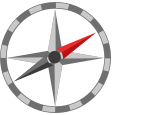**Further exploration**

- You can learn more about eigenanalysis with MATLAB in the online course [Introduction to Linear Algebra with MATLAB](https://matlabacademy.mathworks.com/details/introduction-to-linear-algebra-with-matlab/linalg).

- To learn more about symbolic math, check out the online training course [Introduction to Symbolic Math with MATLAB](https://matlabacademy.mathworks.com/details/introduction-to-symbolic-math-with-matlab/symbolic).

Visualization functions

function setup2DVectorPlot(axisLims) 
% Sets up nice axes for visualizing 2D vectors
    fs = 14; % font size for graph
    ax = gca;
    ax.XAxisLocation = "origin";
    ax.YAxisLocation = "origin";    
    ax.Position = [0.05 0.05 0.9 0.9];
    axis equal tight
    axis(axisLims)
    box on
    xlabel("$x$","Interpreter","latex","fontsize",fs)
    ylabel("$y$","Interpreter","latex","fontsize",fs)
    ax.XTick = round(axisLims(1)):round(axisLims(2));
    ax.XTickLabel = [];
    ax.YTick = round(axisLims(1)):round(axisLims(2));
    ax.YTickLabel = [];
end

% Visualizes a 2D vector with the given name
function plotVector2D(u0,u,name,nameOffset) 
    fs = 14; % font size for the graph
    quiver(u0(1),u0(2),u(1),u(2),"autoscale","off","maxheadsize",1/sqrt(dot(u,u)),"linewidth",1.5)
    offset = null(u')/3*nameOffset;
    text(u0(1) + u(1)/2 + offset(1), u0(2) + u(2)/2 + offset(2),strcat("$",name,"$"), ...
        "Interpreter","latex","fontsize",fs,"HorizontalAlignment","center")
end


Suppress unused suggestions

%#ok<*IJCL> 
%#ok<*NOPRT>
%#ok<*UNRCH>
%#ok<*ASGLU> 
%#ok<*NASGU>